simulink

## Simulink Üzerinden Optimizasyon Yapılacağı için Parametrelerin Başlangıç Değerlerinin Atanması

Kp=1; Kd=1; Ki=1; lambda=0.5; mu=0.5;

## BLDC Motor'un Transfer Fonksiyonu

s = tf('s');
plant_r = 1/(2*s +1);
disp(plant_r)%%

  tf with properties:

       Numerator: {[0 1]}
     Denominator: {[2 1]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



plant_r

plant_r =
 
     1
  -------
  2 s + 1
 
Continuous-time transfer function.
Model Properties


## `Tam Mertebeden PID Kontrolcüsünün Oluşturulması(NOT: PID ve FOPID parametreleri Simunlink Control Design Optimization Toolbox ile Hesaplanmıştır)`

IO_PID = 75.70 + (37.72/s) + 0.0191*s %%

IO_PID =
 
  0.0191 s^2 + 75.7 s + 37.72
  ---------------------------
               s
 
Continuous-time transfer function.
Model Properties


## **FOPID  Parametrelerinin Optimizasyon Sonrası Değerleri**

disp(c2); c2

  zpk with properties:

                Z: {[3×1 double]}
                P: {[3×1 double]}
                K: 1.4759e+03
    DisplayFormat: 'roots'
         Variable: 's'
          IODelay: 0
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]


c2 =
 
  1475.9 s (s+0.2109) (s+0.01658)
  -------------------------------
    s (s+0.08045) (s+0.006072)
 
Continuous-time zero/pole/gain model.


## FOPID ve PID Karşılaştırması

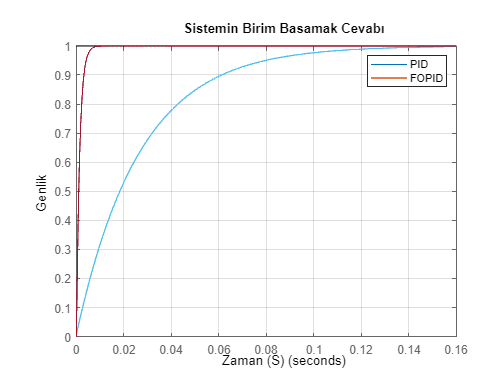

step(feedback(IO_PID*plant_r,1)); hold on; step(feedback(c2*plant_r,1)); legend('PID','FOPID');
grid on; xlabel('Zaman (S)'); ylabel('Genlik'); title('Sistemin Birim Basamak Cevabı');%%

## **FOPID Parametreleri**

Kp

Kp = 283.2323

Ki

Ki = 999.5700

Kd

Kd = 289.6813

lambda

lambda = 0.3919

mu

mu = 0.1504

disp('PID Performans Çıktıları')

PID Performans Çıktıları


stepinfo(feedback(IO_PID*plant_r,1))

ans = struct with fields:
         RiseTime: 0.0586
    TransientTime: 0.1044
     SettlingTime: 0.1042
      SettlingMin: 0.9009
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 0.1953


disp('FOPID Performans Çıktıları')%%

FOPID Performans Çıktıları


stepinfo(feedback(c2*plant_r,1))

ans = struct with fields:
         RiseTime: 0.0030
    TransientTime: 0.0053
     SettlingTime: 0.0053
      SettlingMin: 0.9041
      SettlingMax: 0.9995
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9995
         PeakTime: 0.0380
